# DtFT, rola funkcji okien i liczby próbek

N = 100;

N = 1000;

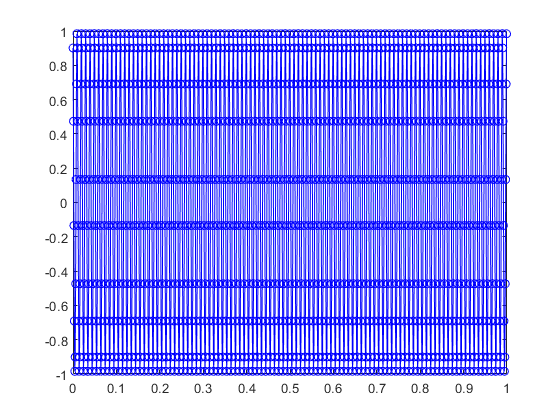

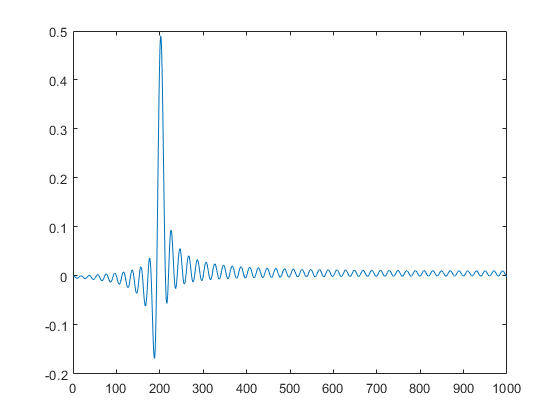


f1 = 100; f2 = 125;
A1 = 1; A2 = 0.0001;

fgen = @(t) A1*cos(2*pi*f1*t+pi/7) +  A2*cos(2*pi*f2*t+pi/11);

fs1000Hz = 1000;
x = fgen(0:1/fs1000Hz:(1/fs1000Hz*(N-1)));

clf
figure
plot(0:1/fs1000Hz:(1/fs1000Hz*(N-1)), x, 'b-o');

Próbki sygnału z oknem prostokątnym, Hamminga, Blackmana, Czebyszewa:

xMultMatrix = [ x;  
        x .* rectpuls(0:1/fs1000Hz:(1/fs1000Hz*(N-1)),(1/fs1000Hz*(N-1)));
        x .* hamming(N)'; 
        x .* chebwin(N, 100)'; 
        x .* chebwin(N, 120)'
    ];


xMultMatrix = [
        x .* chebwin(N, 100)'; 
        x .* chebwin(N, 120)'
    ];



% z zadania 3
f = 0:0.1:500-0.1;
XMultMatrix = zeros(size(xMultMatrix, 1),length(f));

for i=1:size(XMultMatrix,1)
    for itF=1:length(f)
        for itn=0:N-1
            XMultMatrix(i,itF) = XMultMatrix(i,itF) ...
            + XMultMatrix(i,itn+1) ...
            *exp(-1i*2*pi*f(itF)*itn/fs1000Hz);
        end
        % X3(itF) = X3(itF)/N;
    end
    XMultMatrix(i,:) = XMultMatrix(i,:)./N;
end

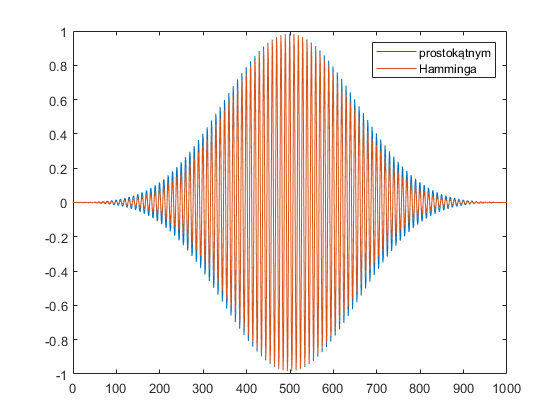

% wykresy time

clf
figure
for i=1:size(xMultMatrix,1)
    plot(fs1000Hz*(0:size(xMultMatrix,2)-1)/size(xMultMatrix,2), real(xMultMatrix(i,:)))
    hold on
    pause(0.5)
end
legend({"prostokątnym", "Hamminga", "Blackmana", "Czebyszewa 100", "Czebyszewa 120"})